B6_1

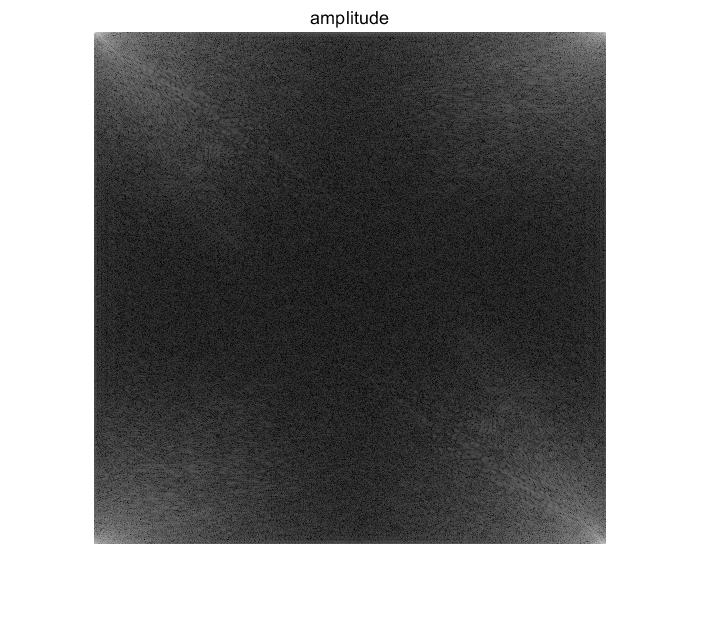

clear
img = imread("lenaG.bmp");
img = im2double(img); % change [0,255] to [0,1] in double type
img_fft = fft2(img);

imshow(log(abs(img_fft)+1),[]) 
% log to reduce the range. plus 1 to make all result larger than 0
title('amplitude')

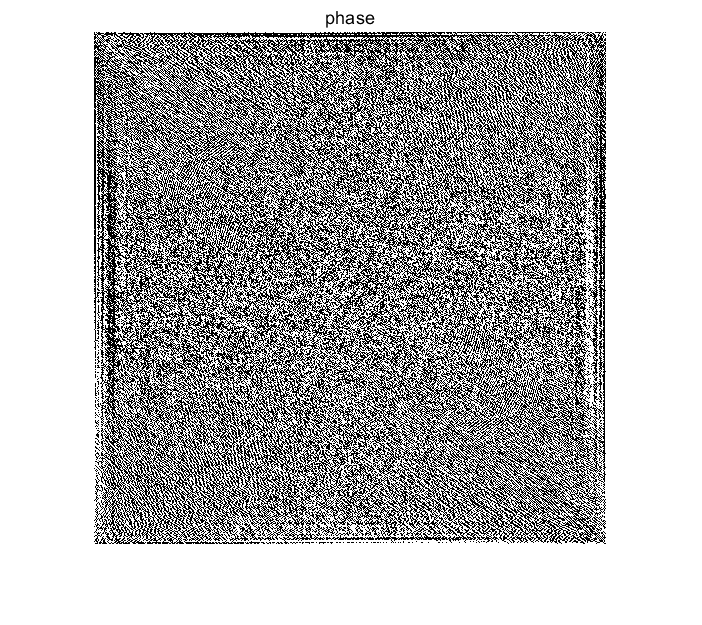

imshow(angle(img_fft)*180/pi)
title('phase')

B6_2 zero frequencies to the centre

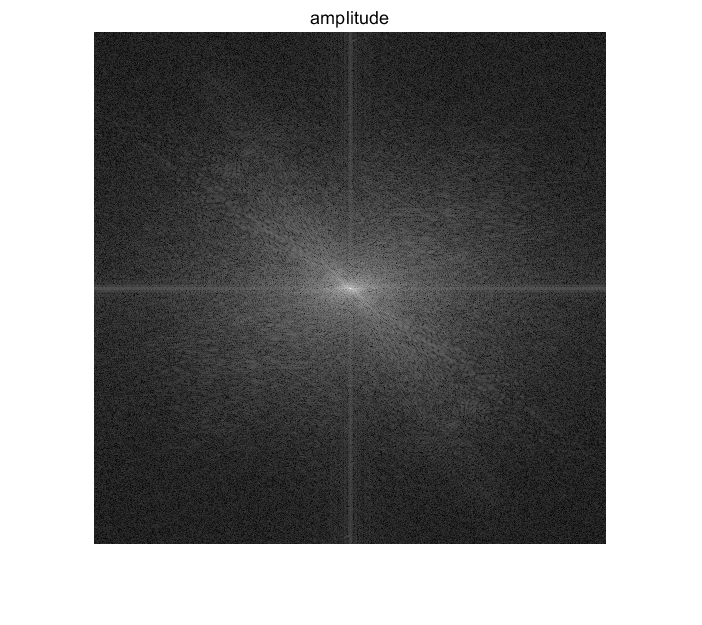

clear
img = imread("lenaG.bmp");
img = im2double(img); % change [0,255] to [0,1] in double type
img_fft = fft2(img);

img_fft = fftshift(img_fft);

imshow(log(abs(img_fft)+1),[]) 
% log to reduce the range. plus 1 to make all result larger than 0
title('amplitude')

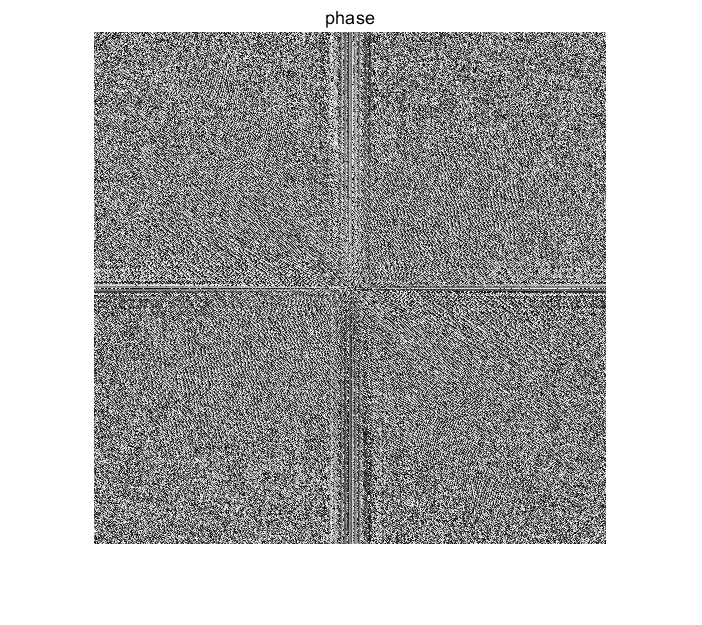

imshow(angle(img_fft)*180/pi,[])
title('phase')